eeg1=strap1.eeg4;
eeg2=strap1.eeg5;
eeg3=strap1.eeg6;
eeg4=strap1.eeg7;
for i=1:1:length(eeg1)
    if eeg1(i)>3.3
        eeg1(i)=3.3;
    end
end
for i=1:1:length(eeg2)
    if eeg2(i)>3.3
        eeg2(i)=3.3;
    end
end
for i=1:1:length(eeg3)
    if eeg3(i)>3.3
        eeg3(i)=3.3;
    end
end
for i=1:1:length(eeg4)
    if eeg4(i)>3.3
        eeg4(i)=3.3;
    end
end

f=length(eeg1)/120;
t=1/f;
t_D=[0:1:length(eeg2)-1]*t;

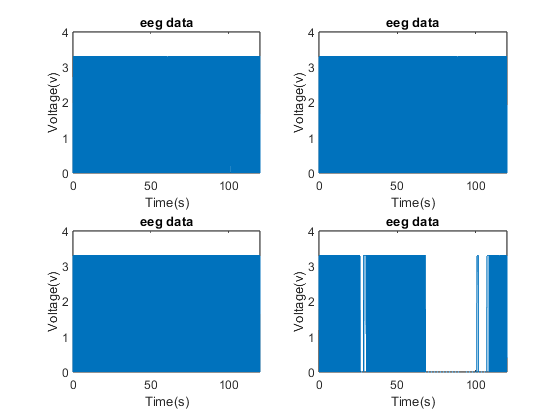

figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg1_Fft=fft(eeg1);
eeg1_Fft(1)=0;
eeg1=ifft(eeg1_Fft);

eeg2_Fft=fft(eeg2);
eeg2_Fft(1)=0;
eeg2=ifft(eeg2_Fft);

eeg3_Fft=fft(eeg3);
eeg3_Fft(1)=0;
eeg3=ifft(eeg3_Fft);

eeg4_Fft=fft(eeg4);
eeg4_Fft(1)=0;
eeg4=ifft(eeg4_Fft);

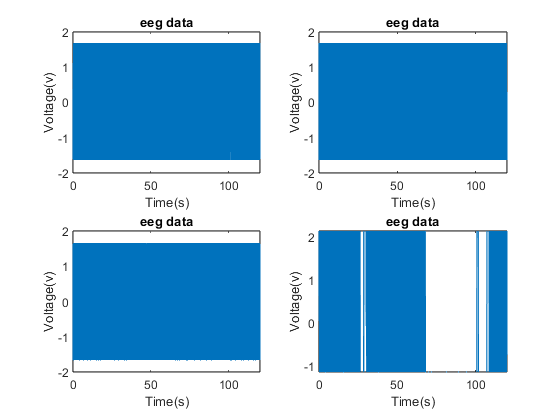

figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

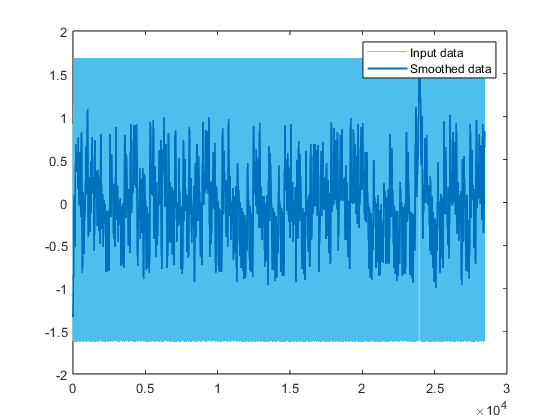

% Smooth input data
eegs1 = smoothdata(eeg1,"movmean",80);

% Display results
clf
plot(eeg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eegs1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

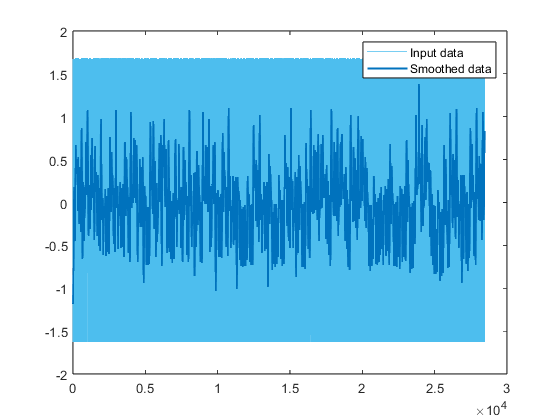

% Smooth input data
eegs2 = smoothdata(eeg2,"movmean",80);

% Display results
clf
plot(eeg2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eegs2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

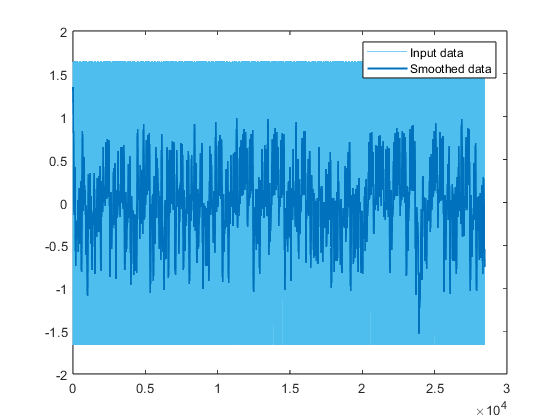

% Smooth input data
eegs3 = smoothdata(eeg3,"movmean",80);

% Display results
clf
plot(eeg3,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eegs3,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

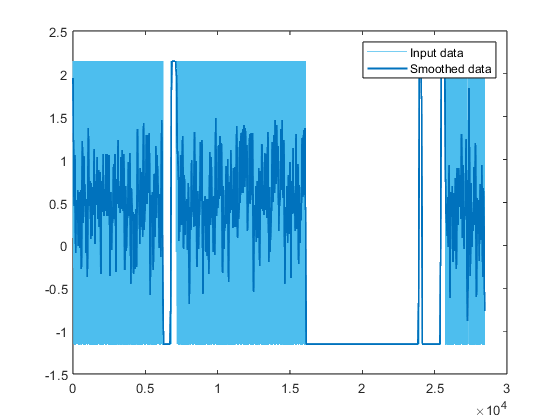

% Smooth input data
eegs4 = smoothdata(eeg4,"movmean",80);

% Display results
clf
plot(eeg4,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eegs4,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

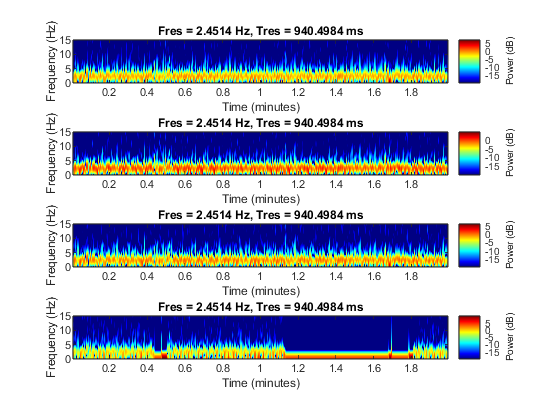

figure;
colormap jet;
subplot(4,1,1)
pspectrum(eeg1,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,2)
pspectrum(eeg2,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,3)
pspectrum(eeg3,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,4)
pspectrum(eeg4,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

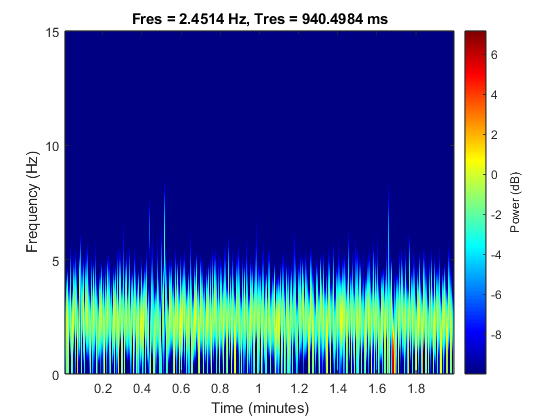


figure;
colormap jet;

pspectrum(eeg1,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

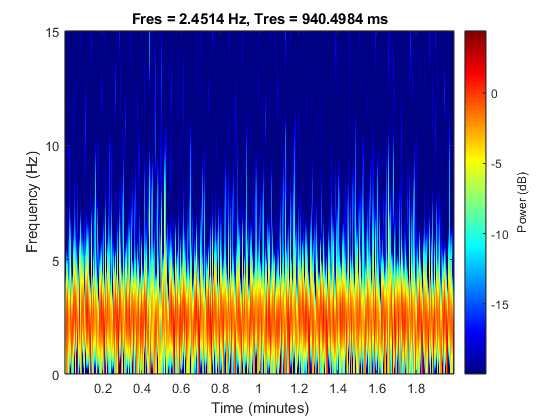

figure;
colormap jet;

pspectrum(eeg2,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

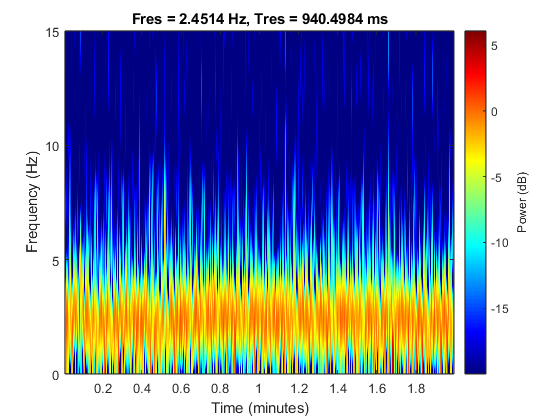

figure;
colormap jet;

pspectrum(eeg3,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

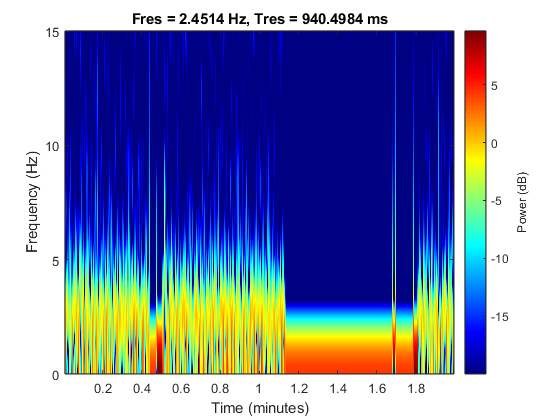

figure;
colormap jet;

pspectrum(eeg4,f,"spectrogram","MinThreshold",-20,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

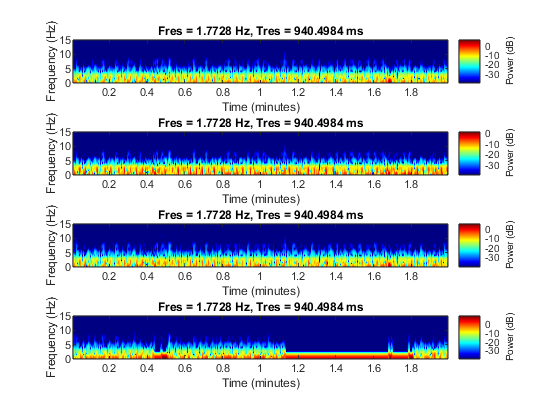

figure;
colormap jet;
subplot(4,1,1)
pspectrum(eegs1,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.8,"OverlapPercent",90)
subplot(4,1,2)
pspectrum(eegs2,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.8,"OverlapPercent",90)
subplot(4,1,3)
pspectrum(eegs3,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.8,"OverlapPercent",90)
subplot(4,1,4)
pspectrum(eegs4,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.8,"OverlapPercent",90)

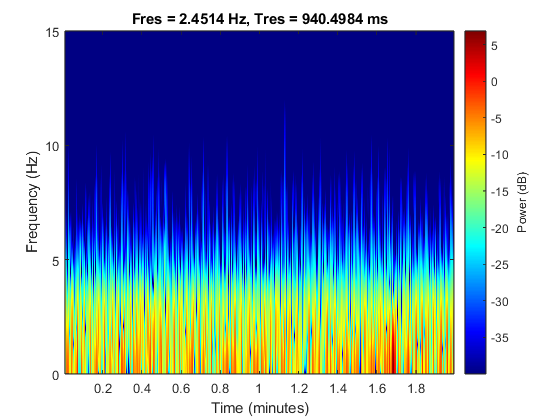

figure;
colormap jet;

pspectrum(eegs1,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

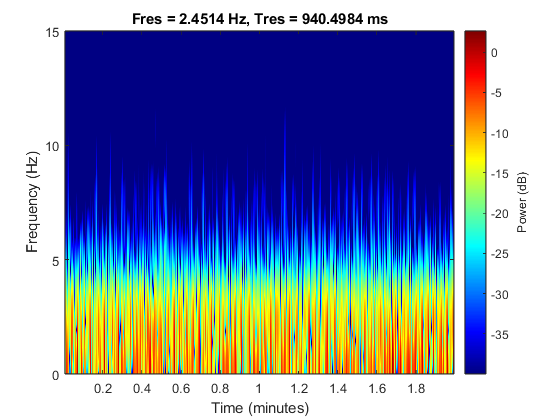

figure;
colormap jet;

pspectrum(eegs2,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

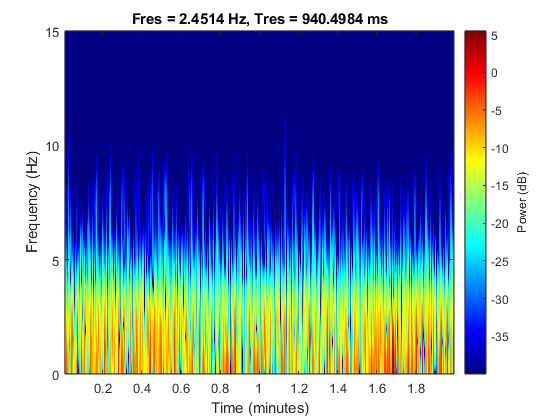

figure;
colormap jet;

pspectrum(eegs3,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

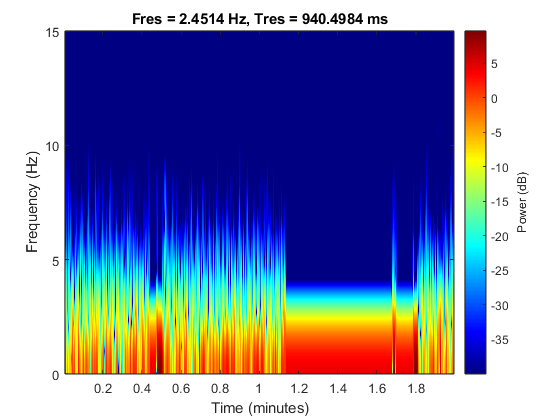

figure;
colormap jet;

pspectrum(eegs4,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

output_eeg_trial1115=[eeg1,eeg2,eeg3,eeg4];
output_eeg_trial1115_smooth=[eegs1,eegs2,eegs3,eegs4];

writematrix(output_eeg_trial1115,'D:\matlab\ymaps_code\data\output_eeg_trial1115.csv');
writematrix(output_eeg_trial1115_smooth,'D:\matlab\ymaps_code\data\output_eeg_trial1115_smooth.csv');